# Example: Solver for Acoustics in 1D with Multipole Sources

This live-script features the following:

- 1D example

- how to set up multipole sources

In 1D, mutipole sources are of the form


$$f(x,t) = \sum_{m=1}^M w_m(t) \delta^{(s_m)}(x-x_{m})$$


where 

- $w_m(t)$ is the time function of the $m$-th term

- $s_m\in\mathbb N$ is the derivative order of the $m$-th term

- $\delta^{(s_m)}(x-x_m)$ is the $s_m$-derivative of the Dirac delta function shifted by $x_m$

- $x_m$ is the center/location of the $m$-th term

clear

domain_x = [0,1];
domain_t = [0,0.7];

% Computational grids and grid spaces
Nx=201;
grid_primal = Grid1DUnifPrimal([0,1],401);
grid_dual   = Grid1DUnifDual(grid_primal);
gsp_P = GridSpace1D(grid_primal); %grid space for pressure
gsp_V = GridSpace1D(grid_dual);   %grid space for velocity
dx = gsp_P.h;

% Acoustic medium parameters
medium = AcousticMedium1D.constant(BetaValue=1,KappaValue=1);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gsp_P,medium);

% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)*dx/cMax; %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output spatial grid and time points
gsp_out   = GridSpace1D(Grid1DUnifPrimal(domain_x,101));
t_pts_out = linspace(domain_t(1),domain_t(2),51);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initializing PML
pml = PML1D(WidthLeft=0.2,WidthRight=0);

% Initialize solver
solver = AcousticSolver1D_PML( ...
    gsp_P,t_pts, ...
    gsp_out,t_pts_out, ...
    medium, pml, ...
    SpatialOrder=4);

Here we initialize several examples of multipole pressure sources.

Single term monopole: $f(x,t) = w_0(t)\delta(x-x_0)$

x0 = 0.33;
s0 = 0;
w0 = @(t) exp(-((t-0.10)/0.025).^2);

monopole = MultipoleComponent1D(x0,s0,TargetField="pressure");
mps0 = MultipoleSrcTerm1D(monopole,w0);

Single term dipole: $f(x,t) = w_1(t)\delta'(x-x_1)$

Typically multipoles are scaled so that the results are comparable between different terms.

x1 = 0.8;
s1 = 1;
w1 = @(t) dx*10*exp(-((t-0.18)/0.035).^2);

dipole = MultipoleComponent1D(x1,s1,TargetField="pressure");
mps1 = MultipoleSrcTerm1D(dipole,w1);

Multipole series: $f(x,t) = w_0(t)\delta(x-x_0) + w_t(t)\delta'(x-x_1)$

mps_series = MultipoleSrcSeries1D([mps0,mps1]);

To generate an acoustic source we apply the discretize method for multipoles.

Approximation order of multipole should match the spatial order of FDM.

appxOrder = 4;
src_monopole = mps0.discretize(gsp_P,gsp_V,appxOrder);
src_dipole   = mps1.discretize(gsp_P,gsp_V,appxOrder);
src_series   = mps_series.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P_monopole,~] = solver.solve(p0,v0,Source=src_monopole);
[P_dipole,~] = solver.solve(p0,v0,Source=src_dipole);
[P_series,~] = solver.solve(p0,v0,Source=src_series);

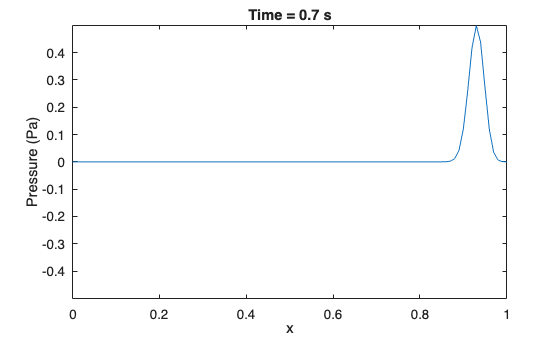

P_monopole.animate(FramePause=0.03);

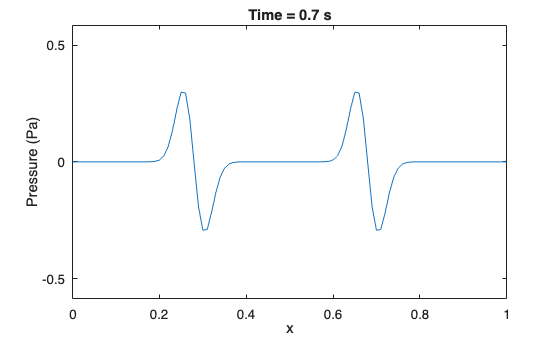

P_dipole.animate(FramePause=0.03);

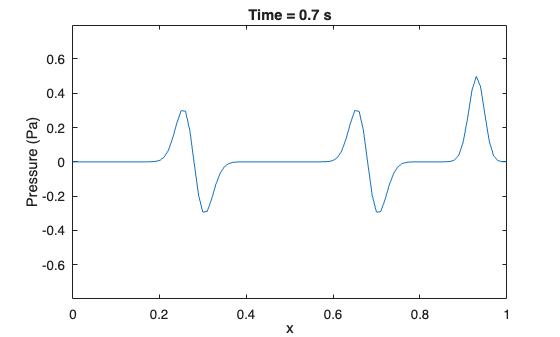

P_series.animate(FramePause=0.03);